Load the Signal

[signal,fs]=audioread("s3.wav");

Visualizing the Signal

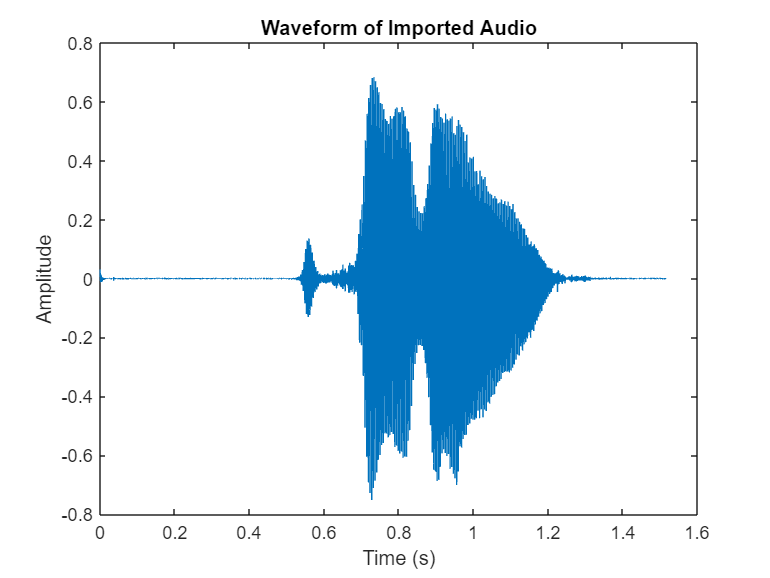

t = (0:length(signal)-1)/fs;   % Time axis
plot(t, signal);
xlabel('Time (s)');
ylabel('Amplitude');
title('Waveform of Imported Audio');

Preemphasising

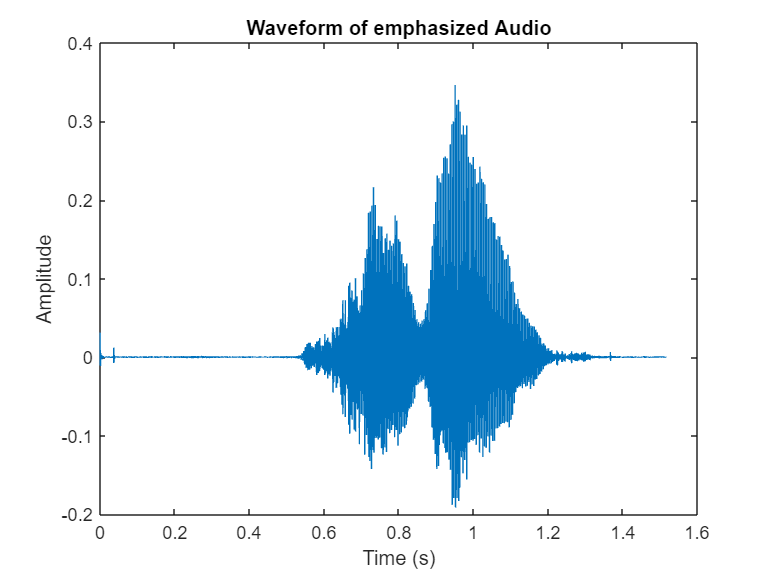

alpha = 0.97;
emphasized = preemphasis(signal, alpha);
plot(t, emphasized);
xlabel('Time (s)');
ylabel('Amplitude');
title('Waveform of emphasized Audio');

Framing

frame_length = 256;
hop_size=100;
frames = frame_signal(emphasized, frame_length, hop_size);
frames

frames =     0.0312    0.0013   -0.0005         0   -0.0005   -0.0005         0    0.0005   -0.0000         0   -0.0005         0    0.0005   -0.0005         0    0.0000   -0.0005    0.0010   -0.0005    0.0005    0.0005   -0.0000   -0.0000   -0.0005         0   -0.0005         0    0.0004    0.0000   -0.0005    0.0010    0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0000   -0.0000   -0.0000         0    0.0005         0    0.0005   -0.0005         0   -0.0005   -0.0005         0         0
   -0.0093    0.0004    0.0005         0    0.0005   -0.0010   -0.0005   -0.0005   -0.0000         0    0.0005   -0.0005   -0.0000   -0.0000         0    0.0000    0.0005         0         0         0    0.0005   -0.0000    0.0010         0    0.0005   -0.0010   -0.0005    0.0005   -0.0005   -0.0005   -0.0005    0.0005   -0.0005    0.0005   -0.0000   -0.0010         0   -0.0000    0.0005    0.0010         0         0   -0.0005   -0.0005   -0.0005         0   -0.0000    0.0005         0

Applying Hamming Window

windowed_frames=apply_window(frames);

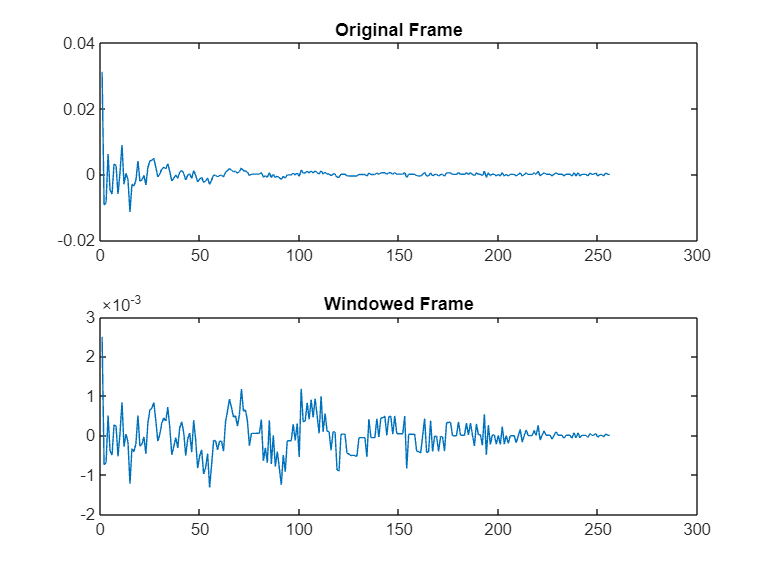

frameIdx = 1;
subplot(2,1,1);
plot(frames(:, frameIdx));
title('Original Frame');

subplot(2,1,2);
plot(windowed_frames(:, frameIdx));
title('Windowed Frame');

[frame_length_windowed,number_of_frames]=size(windowed_frames);
frame_length_windowed

frame_length_windowed = 256

number_of_frames

number_of_frames = 187

Compute the Power Spectrum

nfft = 512;
power_spectrum = compute_power_spectrum(windowed_frames, nfft)

power_spectrum =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000  

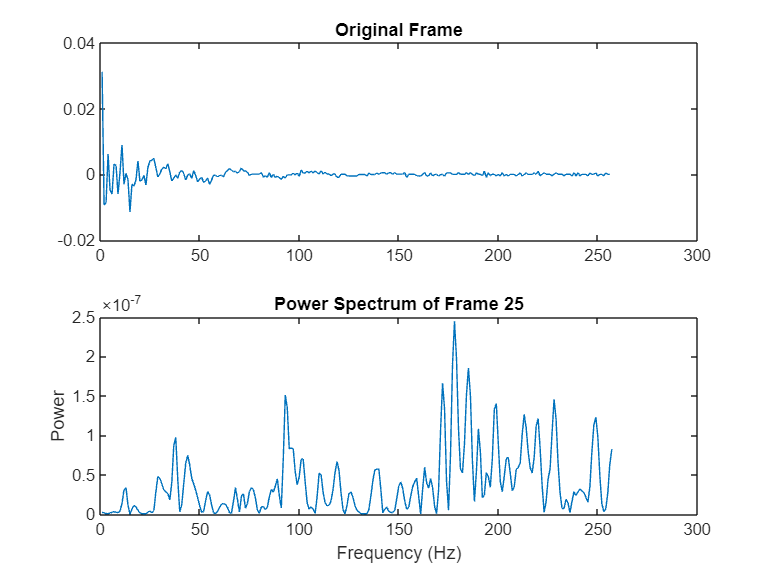

frameIdx = 25;   % pick a frame
plot(power_spectrum(:, frameIdx));
xlabel('Frequency (Hz)');
ylabel('Power');
title(sprintf('Power Spectrum of Frame %d', frameIdx));

Creating Mel Filter Bank and Applying

Num_of_Mel_filters=26;
Melbank_filter=melfb(Num_of_Mel_filters,nfft,fs)

Melbank_filter =          0    0.2000    0.4000    0.2667    0.1333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.1111    0.2222    0.3333    0.2222    0.1111         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

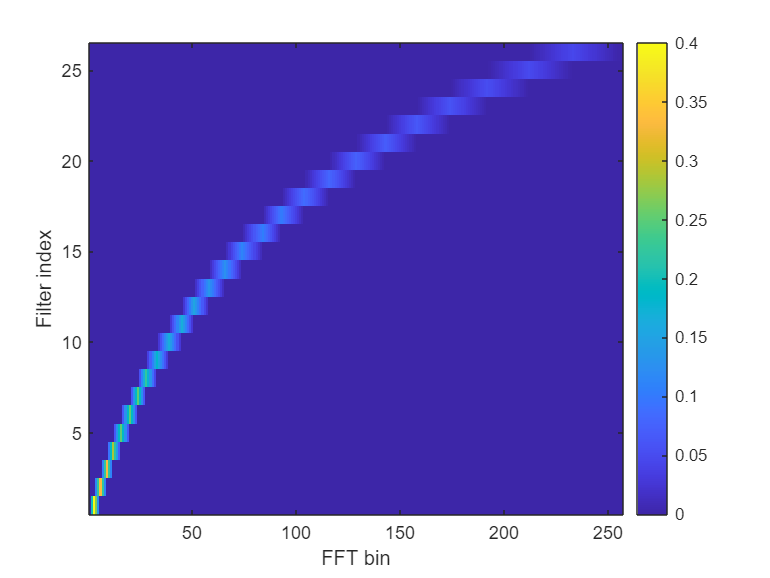

figure;
imagesc(Melbank_filter);
axis xy;
xlabel("FFT bin")
ylabel("Filter index")
colorbar;

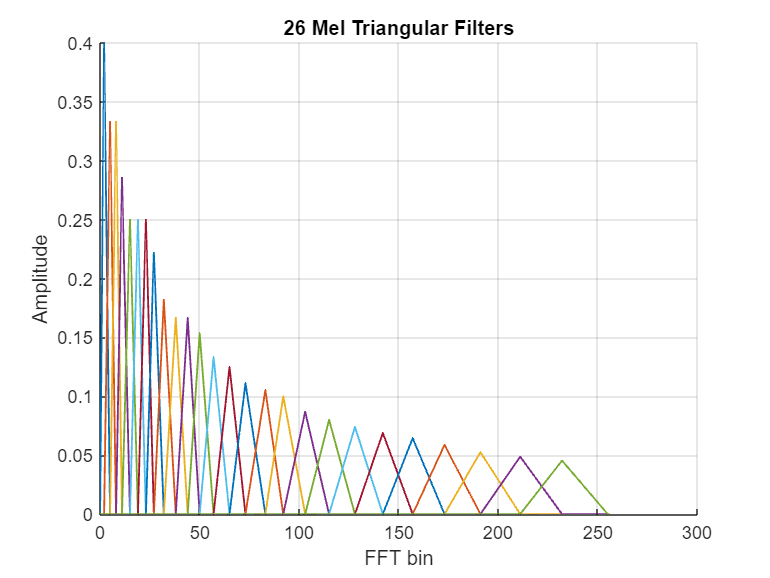

figure;
hold on;

[num_filters, num_bins] = size(Melbank_filter);

for m = 1:num_filters
    plot(0:num_bins-1, Melbank_filter(m,:), 'LineWidth', 1);
end

xlabel('FFT bin');
ylabel('Amplitude');
title('26 Mel Triangular Filters');
grid on;
hold off;

mel_energies = apply_mel_filterbank(power_spectrum, fs, nfft, num_filters)

mel_energies =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    

Mel Energy

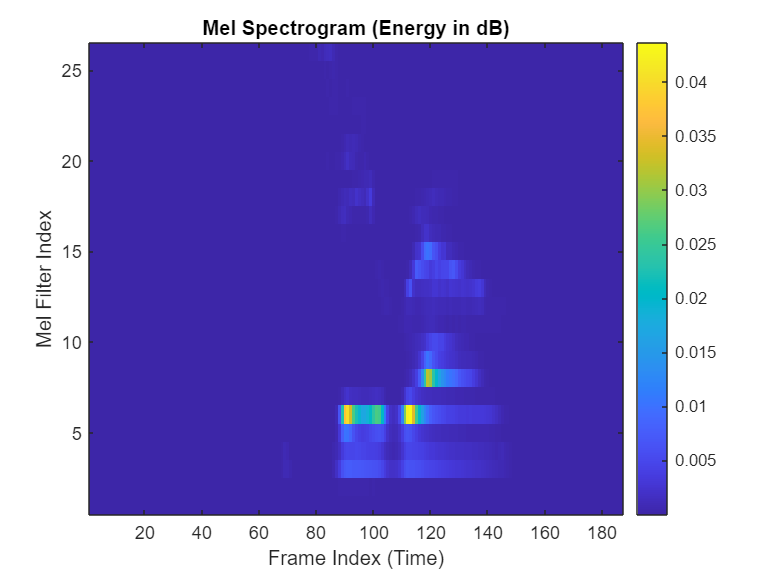

% Plot as an image
imagesc(mel_energies);

% Adjust axes
axis xy;   % put low frequencies at bottom
xlabel('Frame Index (Time)');
ylabel('Mel Filter Index');
title('Mel Spectrogram (Energy in dB)');
colorbar;

Correlation across Frames

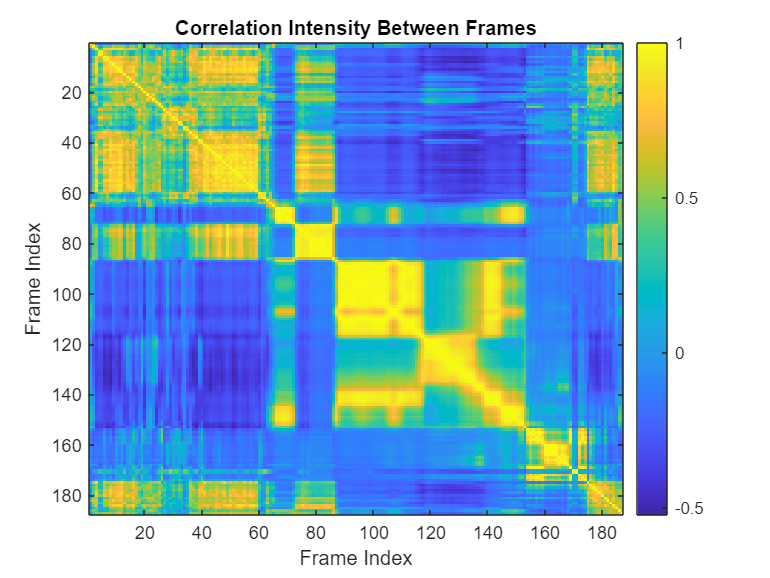

R = corrcoef(mel_energies);   % correlation across frames
imagesc(R);
colorbar;
xlabel('Frame Index');
ylabel('Frame Index');
title('Correlation Intensity Between Frames');

Apply Log

log_mel = apply_log(mel_energies)

log_mel =   -18.5033  -20.7790  -20.5791  -21.9428  -21.1276  -22.0190  -20.8916  -22.1367  -20.9081  -21.8278  -21.0336  -21.0742  -21.1882  -21.4145  -21.4849  -21.4618  -21.2690  -21.8744  -21.6749  -20.8918  -21.7892  -20.8835  -21.2485  -21.0667  -20.7607  -21.7918  -21.5720  -21.1959  -21.6906  -21.4682  -21.1898  -21.5424  -20.3347  -21.9169  -20.7963  -21.8161  -21.9253  -20.7714  -21.1324  -20.7061  -21.9493  -20.8569  -21.5630  -21.7435  -21.2283  -21.6308  -21.0681  -21.4238  -21.1720  -21.8692
  -17.4673  -21.3604  -21.6382  -22.7959  -23.6812  -23.6670  -23.4893  -21.9964  -21.1587  -19.9847  -20.1975  -19.6911  -20.7575  -19.9530  -20.2931  -20.4312  -22.1796  -21.7389  -22.8201  -20.3652  -19.6011  -20.3178  -21.9722  -21.4743  -19.9602  -20.7072  -21.0771  -21.3024  -21.0956  -21.1149  -19.5168  -20.5945  -21.4177  -19.2293  -20.1679  -19.9034  -20.7455  -19.6949  -20.1655  -21.6438  -23.1054  -22.1681  -23.2596  -22.9458  -23.3788  -22.4122  -20.4734  -22.4907  -20.945

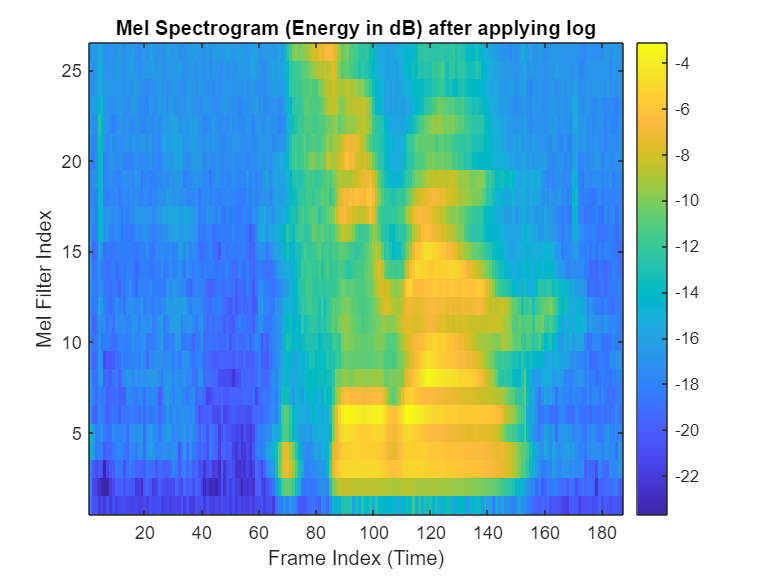

% Plot as an image
imagesc(log_mel);

% Adjust axes
axis xy;   % put low frequencies at bottom
xlabel('Frame Index (Time)');
ylabel('Mel Filter Index');
title('Mel Spectrogram (Energy in dB) after applying log');
colorbar;

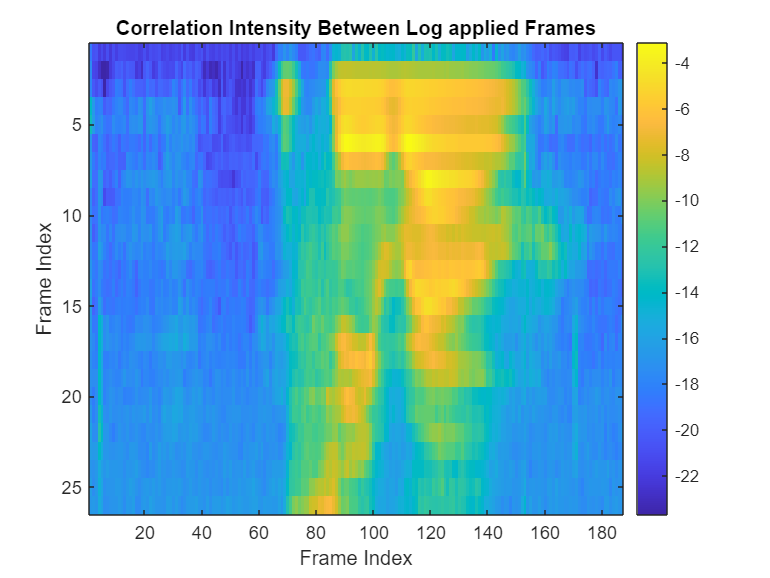

imagesc(log_mel);
colorbar;
xlabel('Frame Index');
ylabel('Frame Index');
title('Correlation Intensity Between Log applied Frames');

Apply Fourier Cosine transform

num_coeffs =13;
mfcc = apply_dct(log_mel, num_coeffs)

mfcc =   -84.6655  -94.0774  -94.1807  -83.6803  -87.5592  -95.7119  -94.7470  -94.8710  -93.8439  -92.4547  -92.8908  -91.8829  -93.2149  -92.0841  -90.7911  -90.8329  -92.0257  -91.9928  -91.0741  -92.0002  -90.9532  -90.3386  -92.1147  -90.9522  -91.0678  -90.5216  -90.0230  -88.5904  -88.2939  -88.3179  -86.7738  -88.8391  -89.0519  -88.6610  -89.6927  -89.9638  -91.1541  -91.4388  -93.0795  -92.6522  -95.9280  -95.5276  -95.2120  -96.1311  -95.9943  -97.5302  -95.8622  -96.8124  -96.2405  -96.5910
    0.2524   -4.0828   -5.6821  -10.5412   -8.8929   -7.3801   -7.1709   -6.6387   -4.7155   -4.0703   -4.7056   -3.5703   -4.3404   -4.1128   -3.2389   -3.6398   -4.6348   -3.6508   -3.1817   -4.7392   -2.6824   -3.1464   -3.0588   -3.6768   -4.2494   -4.2811   -4.5225   -3.6781   -4.3889   -4.5185   -3.6544   -5.0913   -3.9586   -2.2003   -4.2415   -4.0029   -5.3564   -5.3617   -5.5833   -4.9738   -6.8252   -7.6794   -6.1303   -7.6804   -7.5763   -8.7826   -6.0342   -8.2715   -7.6041  

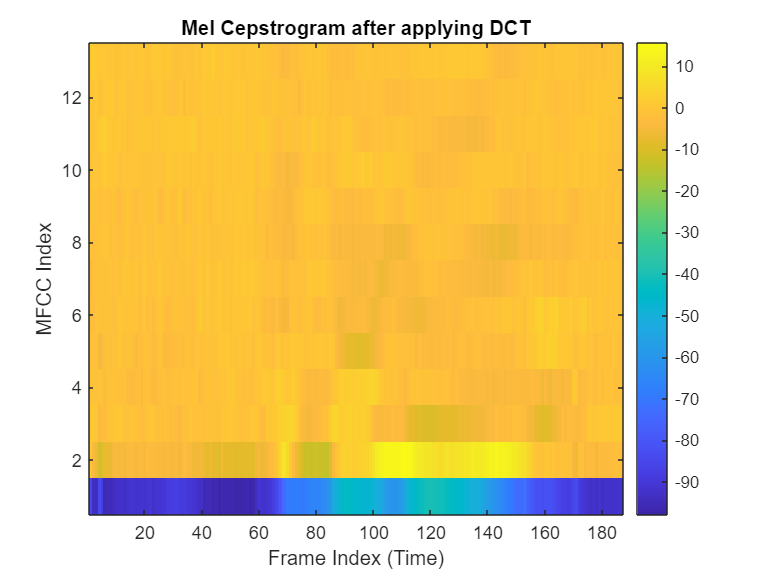

% Plot as an image
imagesc(mfcc)
% Adjust axes
axis xy;   % put low frequencies at bottom
xlabel('Frame Index (Time)');
ylabel('MFCC Index');
title('Mel Cepstrogram after applying DCT');
colorbar;

Apply Delta Fourier Cosine transform

delta_mfcc = compute_delta(mfcc)

delta_mfcc =    25.5138   28.0645   27.7250   23.3975   24.9185   27.5226   27.4325   27.6503   27.6841   27.3343   27.5178   27.1966   27.3294   27.0556   26.8072   26.7763   26.9463   26.8979   26.4760   26.7218   26.8457   26.7516   27.2919   26.5411   26.6601   26.2627   26.2890   25.7919   25.5397   25.6570   25.1386   25.3645   25.9006   26.0240   26.0730   26.5539   26.6072   26.6725   27.0845   27.0119   27.7379   27.7010   27.7567   27.8927   27.8465   28.0168   28.1607   28.1864   28.0650   28.3077
   25.2896   28.1561   27.9879   24.6116   25.8571   27.9723   28.0582   28.1854   28.0170   27.4720   27.7303   27.1495   27.5485   27.0020   26.6564   26.5802   27.0323   27.0254   26.2604   27.0170   26.9427   26.5950   27.0112   26.4948   26.8146   26.5533   26.6087   25.8901   25.8416   26.0966   25.4903   25.9028   26.3562   26.1824   26.4026   26.6615   27.0942   27.3292   27.2298   27.0685   28.1890   28.4512   28.2891   28.4992   28.3928   28.8056   28.7651   28.8421   28.

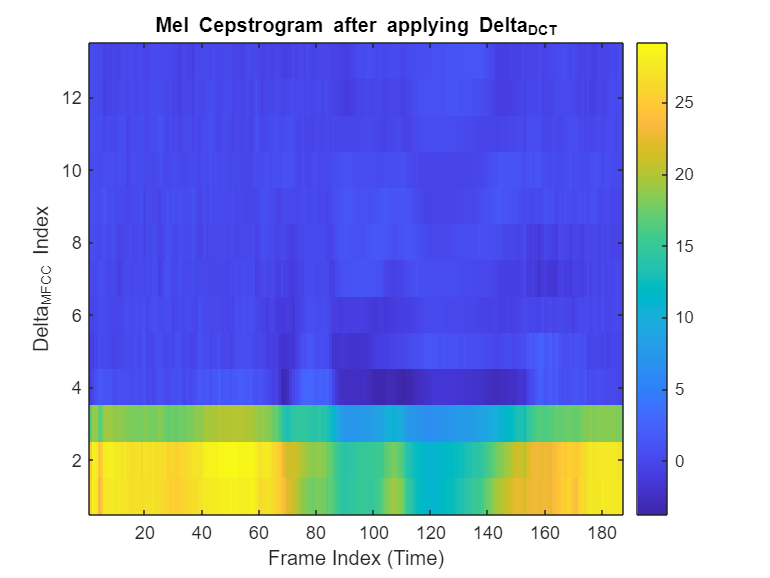

% Plot as an image
imagesc(delta_mfcc)
% Adjust axes
axis xy;   % put low frequencies at bottom
xlabel('Frame Index (Time)');
ylabel('Delta_MFCC Index');
title('Mel Cepstrogram after applying Delta_DCT');
colorbar;

Apply Delta Delta Fourier Cosine transform

delta_delta_mfcc = compute_delta(delta_mfcc)

delta_delta_mfcc =    -1.8018   -1.8369   -1.7039   -1.1986   -1.3892   -1.6124   -1.5580   -1.6364   -1.7061   -1.7438   -1.6973   -1.7675   -1.7364   -1.7514   -1.7837   -1.7988   -1.7942   -1.7554   -1.7777   -1.6137   -1.7544   -1.8112   -1.9052   -1.7535   -1.6434   -1.6135   -1.6982   -1.7076   -1.6039   -1.5729   -1.5729   -1.4768   -1.6116   -1.7121   -1.5818   -1.7387   -1.6258   -1.5303   -1.6662   -1.7175   -1.6191   -1.5269   -1.6327   -1.5880   -1.5987   -1.4839   -1.6159   -1.5606   -1.5150   -1.5881
   -6.1339   -6.5184   -6.2288   -4.9821   -5.4682   -6.0796   -6.0473   -6.1663   -6.3141   -6.2576   -6.1974   -6.1886   -6.2155   -6.1411   -6.1791   -6.1480   -6.1856   -6.2066   -6.1075   -5.9627   -6.2515   -6.1940   -6.4258   -6.1057   -5.9817   -5.9127   -6.0516   -5.9983   -5.8356   -5.8069   -5.7126   -5.6401   -5.9236   -6.0726   -5.9016   -6.1376   -6.0620   -5.9329   -5.9735   -6.0299   -6.1371   -6.0378   -6.2186   -6.1183   -6.0917   -5.9694   -6.2428   -6.1487

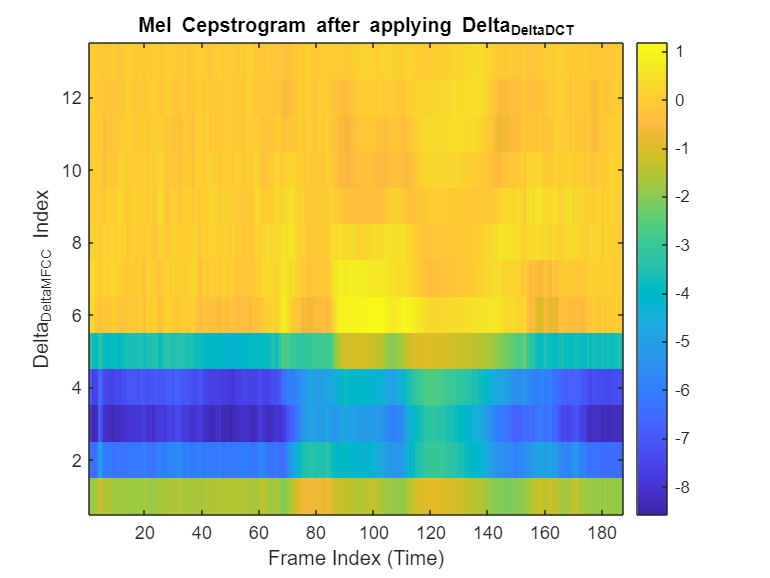

% Plot as an image
imagesc(delta_delta_mfcc)
% Adjust axes
axis xy;   % put low frequencies at bottom
xlabel('Frame Index (Time)');
ylabel('Delta_Delta_MFCC Index');
title('Mel Cepstrogram after applying Delta_Delta_DCT');
colorbar;

Final Feature Matrix

Final_feature_vector=[mfcc;delta_mfcc;delta_delta_mfcc]

Final_feature_vector =   -84.6655  -94.0774  -94.1807  -83.6803  -87.5592  -95.7119  -94.7470  -94.8710  -93.8439  -92.4547  -92.8908  -91.8829  -93.2149  -92.0841  -90.7911  -90.8329  -92.0257  -91.9928  -91.0741  -92.0002  -90.9532  -90.3386  -92.1147  -90.9522  -91.0678  -90.5216  -90.0230  -88.5904  -88.2939  -88.3179  -86.7738  -88.8391  -89.0519  -88.6610  -89.6927  -89.9638  -91.1541  -91.4388  -93.0795  -92.6522  -95.9280  -95.5276  -95.2120  -96.1311  -95.9943  -97.5302  -95.8622  -96.8124  -96.2405  -96.5910
    0.2524   -4.0828   -5.6821  -10.5412   -8.8929   -7.3801   -7.1709   -6.6387   -4.7155   -4.0703   -4.7056   -3.5703   -4.3404   -4.1128   -3.2389   -3.6398   -4.6348   -3.6508   -3.1817   -4.7392   -2.6824   -3.1464   -3.0588   -3.6768   -4.2494   -4.2811   -4.5225   -3.6781   -4.3889   -4.5185   -3.6544   -5.0913   -3.9586   -2.2003   -4.2415   -4.0029   -5.3564   -5.3617   -5.5833   -4.9738   -6.8252   -7.6794   -6.1303   -7.6804   -7.5763   -8.7826   -6.0342   -8.

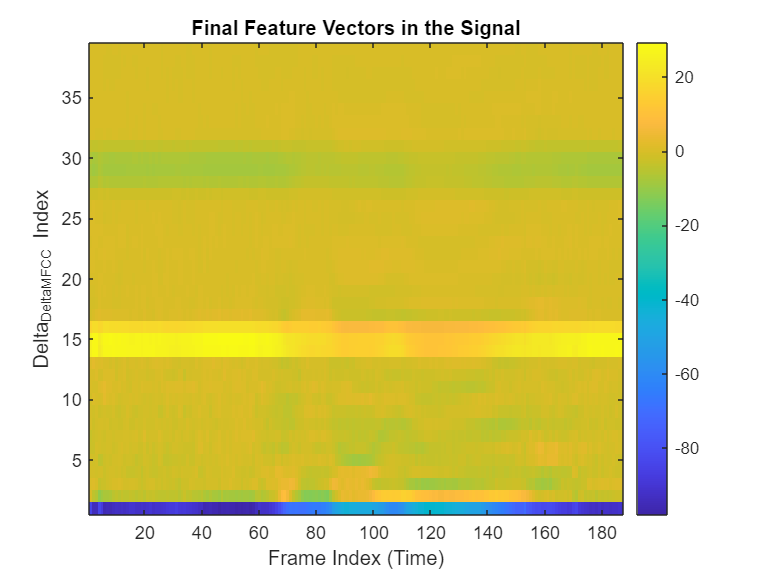

% Plot as an image
imagesc(Final_feature_vector)
% Adjust axes
axis xy;   % put low frequencies at bottom
xlabel('Frame Index (Time)');
ylabel('Delta_Delta_MFCC Index');
title('Final Feature Vectors in the Signal');
colorbar;